# **RT-QIBC**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
m = matfile([dataDir filesep 'gemDbox_alldata.mat']);

**Load data (subsample G1)**

ttestData = {};
mids = {};
percs = {};
scale_edu = [];

rng(1)
for e = [1:3]
    dat = m.S(1,e);
    dat = dat{1};
    gate = m.gates_all(1,e);
    gate = gate{1};
    scale_edu(e) = m.medEdU_all(1,e);
    
    conds=[1 2];
    
    xval = 'YFP1';
    yval = 'FarRed1';
    
    f1 = figure;
    test = {};
    ally = [];
    group = [];
    for i = 1:length(conds)
        condition = conds(i);
        xdata =dat(condition).(xval);
        %ydata = dat(condition).(yval)/medEdU;
        ydata = dat(condition).(yval);      
 
        inds = dat(condition).POI(:,1) <= 1.25 * dat(condition).framesPerHr &...
            dat(condition).POI_time(:,3) <= .5 & dat(condition).YFP1 > gate.YFP1_S(2);
        if condition == 2
            %inds = inds & dat(condition).YFP2 > 2^9;
            inds = inds & dat(condition).YFP2 > median(dat(condition).YFP2);
        else
            inds = inds & dat(condition).YFP2 < gate.YFP2_G1(2);
        end
        xdata=xdata(inds);
        ydata = ydata(inds);
        
        ydata(ydata<0) = [];
        test{i} = ydata;
        ally = [ally; ydata];
        group = [group; repmat(i,size(ydata))];
    end
    
    %%% G1 levels
    condition = 1;
    xdata =dat(condition).(xval);
    %ydata = dat(condition).(yval)/medEdU;
    ydata = dat(condition).(yval);      

    inds =dat(condition).POI_time(:,1) <= 2 & dat(condition).POI_time(:,1)>1 ...
        & isnan(dat(condition).POI_time(:,4)) & dat(condition).FarRed1 < 2^9 & dat(condition).YFP1 > gate.YFP1_G1(1);
    
    xdata=xdata(inds);
    ydata = ydata(inds);
    
    inds = randsample(length(xdata),100);
    xdata=xdata(inds);
    ydata = ydata(inds);
    
    ydata(ydata<0) = [];
    test{3} = ydata;
    ally = [ally; ydata];
    group = [group; repmat(3,size(ydata))];
    
    
    ttestData{e,1} = test{1};
    ttestData{e,2} = test{2};
    ttestData{e,3} = test{3};
    
    
    %%Plot Cdt1 time since S start
    %%%
    conds=[1];
    poiAligned=3;
    offset=-1;
    
    gateVals = {{},{},{}};
    rangeVals = {{}, {}, {}};
    
    edges = (0:1/dat(1).framesPerHr:10)*60;
    midpoints = edges + (edges(2) -edges(1))/2;
    midpoints = midpoints(1:end-1);
    
    
    ind= gate_vals(dat(1), gateVals{i}, rangeVals{i});
    xdata = dat(1).POI_time(ind,poiAligned)*60;
    ydata = [];
    ydata(:, 1) = (dat(1).YFP1(ind));
    ydata(:, 2) = (dat(1).YFP2(ind));
    ydata(:, 3) = (dat(1).FarRed1(ind)) ;
    
    threshs ={{gate.YFP1_S(2), -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',edges);
    
    threshs2 ={{gate.YFP1_G1(2) - (gate.YFP1_G1(2) - gate.YFP1_S(1))/2, -1}, {gate.YFP2_G1(2), 1}, {gate.FarRed1_G1(2), 1}};
    [binData2, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs2, 'Edges',edges);
    
    mids{e} = midpoints;
    percs{e} = binData(1).perc';
    
    percs2{e} = binData2(1).perc';
    
end
scale_edu_cell = num2cell(repmat(scale_edu',1,3));

**Plot degradation curves**

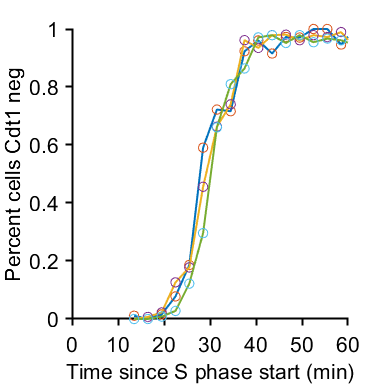

figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
for i = 1:3
    %%% Plot two black
    plot(mids{i},percs{i},'LineWidth',1.5);
    scatter(mids{i},percs{i},50);
    ylabel('Percent cells Cdt1 neg');xlabel('Time since S phase start (min)');
    xlim([0 60])
    ylim([0 1])
    xticks(0:10:60)
    
end

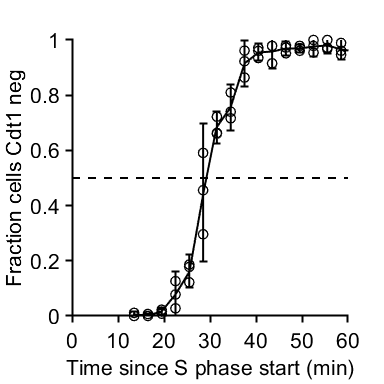


figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
midmat = mids{1};
percmat = cell2mat(percs);
meanperc = mean(percmat,2);
stdperc = tinv(0.95,length(percs)-1)*std(percmat,[],2)/sqrt(3);


errorbar(midmat,meanperc,stdperc,'k','LineWidth',1.5);
scatter([mids{1}],reshape([percs{1}],[],1),50,'ko','LineWidth',1);
scatter([mids{2}],reshape([percs{2}],[],1),50,'ko','LineWidth',1);
scatter([mids{3}],reshape([percs{3}],[],1),50,'ko','LineWidth',1);

ylabel('Fraction cells Cdt1 neg');xlabel('Time since S phase start (min)');
xlim([0 60])
ylim([0 1])
h = hline(.5, 'k--');
xticks(0:10:60)
set(h, 'LineWidth', 1.5);
set(gca,'TickDir','out')
pbaspect([1 1 1])

print_pdf([pwd() '\Figs\Cdt1cumulative.pdf'])